%Working with supposedly infinite control points
%CHANGES: 24/02/2024 changed rep = order-2 to rep = order-3
% /\ CHANGE REVOKED - EXTRA STACK NEEDED FOR HIGHER DERIVATIVES
%--removing a stacked CP from either end of curve
%Circular path: targets = [50,0; 23,8; 5,29; 1,57; 12,83; 36,98; 64,98; 88,83; 99,57; 95,29; 77,8];
%Position
%Control Points
order = 7;
targets = [50,0; 23,8; 5,29; 1,57; 12,83; 36,98; 64,98; 88,83; 99,57; 95,29; 77,8];
CP = points(targets, order)

CP =     50     0
    50     0
    50     0
    50     0
    50     0
    50     0
    23     8
     5    29
     1    57
    12    83


CPx = CP(:,1);
CPy = CP(:,2);
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 0.01;
%Knot Vector
knot = knotvect(CP, order, pmin, pmax, pstep)

knot =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    4.0000    8.0000   12.0000   16.0000   20.0000   24.0000   28.0000   32.0000   36.0000   40.0000   44.0000   48.0000   52.0000   56.0000   59.9400   59.9500   59.9600   59.9700   59.9800   59.9900   60.0000


ksz = size(knot);
validpmin = knot(1, order);
validpmax = knot(1, (ksz(1,2)-order+1));
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
order = 6;
CP = DCP(CP, knot, order)

CP =          0         0
         0         0
         0         0
         0         0
         0         0
   -6.7669    2.0050
   -4.5000    5.2500
   -1.0000    7.0000
    2.7500    6.5000
    6.0000    3.7500


knot = Dkn(knot)

knot =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    4.0000    8.0000   12.0000   16.0000   20.0000   24.0000   28.0000   32.0000   36.0000   40.0000   44.0000   48.0000   52.0000   56.0000   59.9400   59.9500   59.9600   59.9700   59.9800   59.9900


VelMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
VMagMAT = absBS(VelMAT);
order = 5;
CP = DCP(CP, knot, order)

CP =          0         0
         0         0
         0         0
         0         0
   -1.6968    0.5028
    0.5667    0.8112
    0.8750    0.4375
    0.9375   -0.1250
    0.8125   -0.6875
    0.2500   -0.9375


knot = Dkn(knot)

knot =     0.0200    0.0300    0.0400    0.0500    0.0600    4.0000    8.0000   12.0000   16.0000   20.0000   24.0000   28.0000   32.0000   36.0000   40.0000   44.0000   48.0000   52.0000   56.0000   59.9400   59.9500   59.9600   59.9700   59.9800


AccMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
AMagMAT = absBS(AccMAT);
order = 4;
CP = DCP(CP, knot, order)

CP =          0         0
         0         0
         0         0
   -0.4258    0.1262
    0.5659    0.0771
    0.0771   -0.0934
    0.0156   -0.1406
   -0.0312   -0.1406
   -0.1406   -0.0625
   -0.1250         0


knot = Dkn(knot)

knot =     0.0300    0.0400    0.0500    0.0600    4.0000    8.0000   12.0000   16.0000   20.0000   24.0000   28.0000   32.0000   36.0000   40.0000   44.0000   48.0000   52.0000   56.0000   59.9400   59.9500   59.9600   59.9700


JerkMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
JMagMAT = absBS(JerkMAT);
order = 3;
CP = DCP(CP, knot, order)

CP =          0         0
         0         0
   -0.1070    0.0317
    0.2479   -0.0123
   -0.1222   -0.0426
   -0.0154   -0.0118
   -0.0117         0
   -0.0273    0.0195
    0.0039    0.0156
   -0.0039    0.0156


knot = Dkn(knot)

knot =     0.0400    0.0500    0.0600    4.0000    8.0000   12.0000   16.0000   20.0000   24.0000   28.0000   32.0000   36.0000   40.0000   44.0000   48.0000   52.0000   56.0000   59.9400   59.9500   59.9600


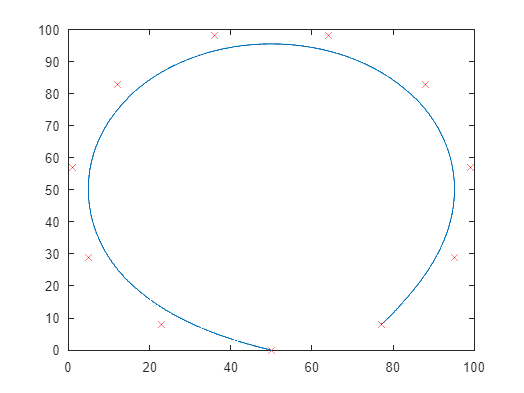

SnapMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
SMagMAT = absBS(SnapMAT);
plot(PosMAT(:,1),PosMAT(:,2))
hold on
scatter(CPx, CPy, 60, 'red', 'X')
hold off

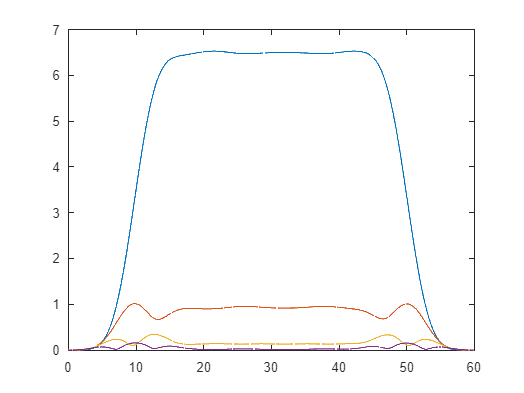

%plot(VelMAT(:,1),VelMAT(:,2))
%plot(AccMAT(:,1),AccMAT(:,2))
plot(VMagMAT(:,1)/100, VMagMAT(:,2))
hold on
plot(AMagMAT(:,1)/100, AMagMAT(:,2))
%hold off
%plot(JerkMAT(:,1),JerkMAT(:,2))
%plot(SnapMAT(:,1),SnapMAT(:,2))
plot(JMagMAT(:,1)/100, JMagMAT(:,2))
%hold on
plot(SMagMAT(:,1)/100, SMagMAT(:,2))
hold off

function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 1;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    sz = size(CP);
    P = sz(1,1);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end
